### Parámetros mecanismo 

%constantes
g = 9.81;

%Parámetros Mecánicos
m_m = 0.00339;    % Masa del Motor
m_b = 0.01056;    % Masa del brazo 
Lm = 0.135;     % Distancia hasta el motor 
Lb = 0.056;     % Distancia hasta el centro de masa

torqueB= m_b*Lb; %Torque genrado por el brazo al utilizar el centro de masa general
%torqueB1= m_b2*Lb2-m_b1*Lb1;

J_b = 0.00014;    % Momento de Inercia brazo 
J_m = 1/12*m_m*((11.4*10^-3)^2+(7*10^-3)^2);    % Momento de Inercia Motor
J = J_m + J_b;       % Momento de Inercia Total
betaF = 0.34*2*J;   % Coeficiente de fricción antes estaba en (0.5*2*Jb)
theta_ref = 80;      % Momento de Inercia Total 


Kf = 0.001191 %0.0015404 %Constante del motor (N/%PWM), El valor de Excel lo peta todo: 0.0015 (F/%PWM)

Kf = 0.0012

KPWM_ang = 0.7162;  % PWM/Angulo


## Linealización del sistema

Primero, la ecuación diferencial, es la siguiente:


$$\begin{array}{l}
\dot{x_1 } =x_2 \\
\dot{x_2 =-\frac{\beta }{J}x_2 -\frac{c}{J}\cdot \textrm{sen}\left(x_1 \right)+\frac{a}{J}u} 
\end{array}$$


syms u b c a x1 x2

g = 9.81; %Gravedad
m_m = 0.00339;    % Masa del Motor
m_b = 0.01056;    % Masa del brazo 
l_m = 0.135;     % Distancia hasta el motor 
l_b = 0.056;     % Distancia hasta el centro de masa
J_b = 0.00014;    % Momento de Inercia brazo 
J_m = 1/12*m_m*((11.4*10^-3)^2+(7*10^-3)^2);    % Momento de Inercia Motor
betaF = 0.34*2*J;   % Coeficiente de fricción antes estaba en (0.5*2*Jb)
theta_ref = 60;      % Momento de Inercia Total 
Kf = 0.001191 %0.0015404 %Constante del motor (N/%PWM)

Kf = 0.0012


%Asignar valores a variables simbolicas

J = J_m + J_b;       % Momento de Inercia Total

dx1 = x2

$$dx1 = x_{2}$$

dx2 = -(b/J)*x2 - (c/J)*sind(x1) + (a/J)*u

$$dx2 = \frac{36893488147419103232\,a\,u}{5166953535204153}-\frac{36893488147419103232\,b\,x_{2}}{5166953535204153}-\frac{36893488147419103232\,c\,\sin\left(\frac{\pi \,x_{1}}{180}\right)}{5166953535204153}$$

A = jacobian([dx1;dx2],[x1,x2])

$$A = \left(\begin{array}{cc} 0 & 1\\ -\frac{9223372036854775808\,\pi \,c\,\cos\left(\frac{\pi \,x_{1}}{180}\right)}{232512909084186885} & -\frac{36893488147419103232\,b}{5166953535204153} \end{array}\right)$$

B = jacobian([dx1;dx2],u)

$$B = \left(\begin{array}{c} 0\\ \frac{36893488147419103232\,a}{5166953535204153} \end{array}\right)$$





a = Kf*l_m;
b = betaF;
c = (l_b*m_b+l_m*m_m)*g;

u=theta_ref;
x1 = asind(u*a/c);
x2 = 0;

Aa = eval(A)%Matriz A del sistema linealizado

Aa =          0    1.0000
   -0.4464   -0.6800


Bb = eval(B)%Matriz B del sistema linealizado

Bb =          0
    1.1480


C = [1,0];

[num, den] = ss2tf(Aa,Bb,[1,0;0,1],zeros(2,1))

num =          0         0    1.1480
         0    1.1480         0


den =     1.0000    0.6800    0.4464


s=tf("s");
FuncionTransfer = num(1,3)/(den(1,1)*s^2 + den(1,2)*s + den(1,3))

FuncionTransfer =
 
          1.148
  ---------------------
  s^2 + 0.68 s + 0.4464
 
Continuous-time transfer function.
Model Properties


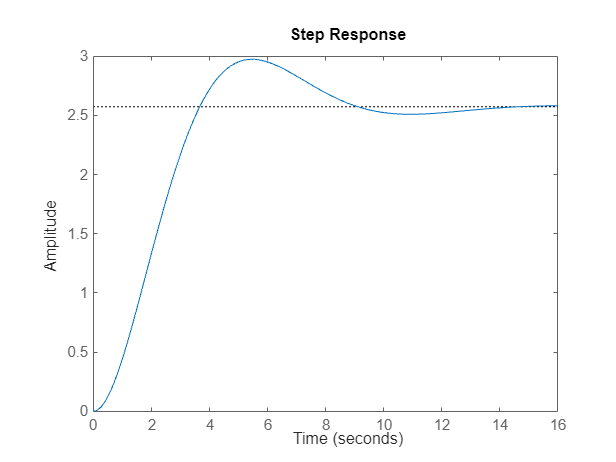

step(FuncionTransfer)


%Polos del sistema
polos_sistema = pole(FuncionTransfer)

polos_sistema =   -0.3400 + 0.5752i
  -0.3400 - 0.5752i


### H_inf

Establecer pesos para controlador


% Crear el sistema de plantas
G = ss(Aa,Bb,C,0)

G =
 
  A = 
            x1       x2
   x1        0        1
   x2  -0.4464    -0.68
 
  B = 
          u1
   x1      0
   x2  1.148
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


rango = 1;
% Construir el sistema aumentado para el diseño H∞

## Filtros

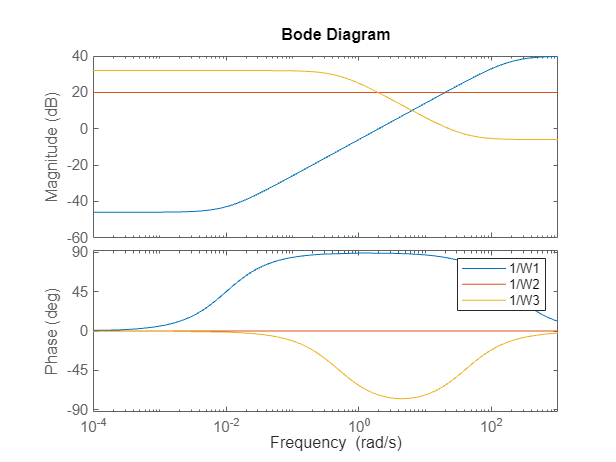

% Definir parámetros del filtro de desempeño
omega_b = 200;  % Frecuencia de cruce de banda deseada [rad/s]
omega_p = 1;   % Frecuencia a la que se atenúa
M = 100;        % Máxima sensibilidad permitida

% Definir el filtro de desempeño Wp
Wp = tf([1 omega_b], [M omega_p]);

% Definir parámetros del filtro de energía
a_u = 10;    % Límite de energía de la señal de control

% Definir el filtro de energía Wu
Wu = tf([1], [a_u]);

% Definir parámetros del filtro de sensibilidad
Ms = 0.5;       % Máxima sensibilidad permitida
omega_s = 1;  % Frecuencia de cruce de la sensibilidad
As = 0.025;     % Atenuación en bajas frecuencias

% Definir el filtro de sensibilidad Ws
Ws = tf([1/Ms omega_s], [1 omega_s/As]);


bode(1/Wp,1/Wu,1/Ws)
legend('1/W1','1/W2','1/W3')


W1 = Wp;
W2 = Wu;
W3 = Ws;
P = augw(G, W1, W2, W3)

P =
 
  A = 
            x1       x2       x3       x4
   x1    -0.01        0       -1        0
   x2        0      -40        8        0
   x3        0        0        0        1
   x4        0        0  -0.4464    -0.68
 
  B = 
          u1     u2
   x1      1      0
   x2      0      0
   x3      0      0
   x4      0  1.148
 
  C = 
           x1      x2      x3      x4
   y1       2       0   -0.01       0
   y2       0       0       0       0
   y3       0  -9.875       2       0
   y4       0       0      -1       0
 
  D = 
         u1    u2
   y1  0.01     0
   y2     0   0.1
   y3     0     0
   y4     1     0
 
Input groups:       
    Name    Channels
     U1        1    
     U2        2    
                    
Output groups:      
    Name    Channels
     Y1      1,2,3  
     Y2        4    
                    
Continuous-time state-space model.



% Diseño del controlador H_infinito
ncont = 1;
nmeas = 1;
[K,CL,gamma,info] = hinfsyn(P,nmeas,ncont)

K =
 
  A = 
               x1          x2          x3          x4
   x1       -0.01   -5.96e-17  -1.691e-14  -3.292e-15
   x2   1.989e-12         -40           8  -1.835e-13
   x3   7.119e-12  -1.188e-14  -3.372e-12           1
   x4        3487      -5.097       -1652      -326.7
 
  B = 
               u1
   x1           1
   x2  -6.187e-15
   x3  -2.214e-14
   x4  -7.038e-15
 
  C = 
          x1     x2     x3     x4
   y1   3037  -4.44  -1438   -284
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


gamma = 0.9446

info =   hinfINFO with properties:

    gamma: 0.9446
        X: [4×4 double]
        Y: [4×4 double]
       Ku: [3.0375e+03 -4.4396 -1.4383e+03 -283.9582]
       Kw: [321.5859 -0.5368 -151.3125 -29.6562]
       Lx: [4×1 double]
       Lu: 0
     Preg: [5×2 ss]
       AS: [2×2 ss]


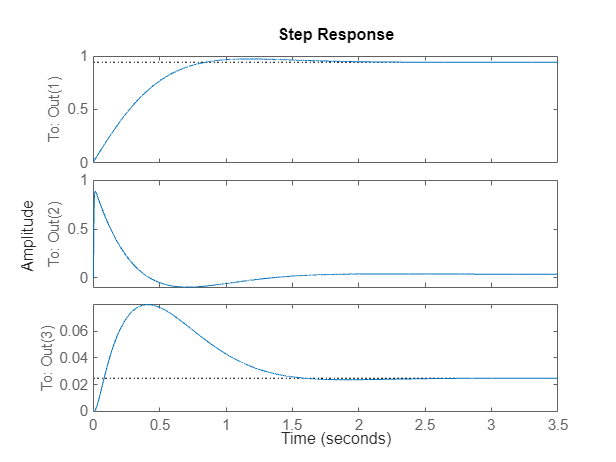

step(CL)

K

K =
 
  A = 
               x1          x2          x3          x4
   x1       -0.01   -5.96e-17  -1.691e-14  -3.292e-15
   x2   1.989e-12         -40           8  -1.835e-13
   x3   7.119e-12  -1.188e-14  -3.372e-12           1
   x4        3487      -5.097       -1652      -326.7
 
  B = 
               u1
   x1           1
   x2  -6.187e-15
   x3  -2.214e-14
   x4  -7.038e-15
 
  C = 
          x1     x2     x3     x4
   y1   3037  -4.44  -1438   -284
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


eig(K)

ans =  -321.5416
   -0.0100
   -5.1406
  -39.9958



L = K*G;
tf(L)

ans =
 
                   3487 s^3 + 1.419e05 s^2 + 9.641e04 s + 6.227e04
  ---------------------------------------------------------------------------------
  s^6 + 367.4 s^5 + 1.497e04 s^4 + 7.643e04 s^3 + 5.229e04 s^2 + 3.003e04 s + 295.1
 
Continuous-time transfer function.
Model Properties


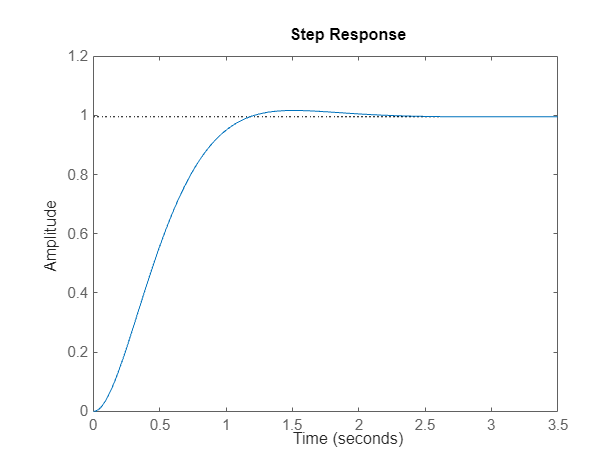

figure
cl = feedback(K*G, 1);
step(cl)

wb = bandwidth(cl)/(2*pi) %Ancho de Banda

wb = 0.4747

eig(cl)

ans = 1.0e+02 *

  -3.2158 + 0.0000i
  -0.4000 + 0.0000i
  -0.0256 + 0.0209i
  -0.0256 - 0.0209i
  -0.0034 + 0.0058i
  -0.0034 - 0.0058i


[wn, Z, p] = damp(cl)

wn =     0.6682
    0.6682
    3.3010
    3.3010
   39.9959
  321.5759


Z =     0.5089
    0.5089
    0.7750
    0.7750
    1.0000
    1.0000


p = 1.0e+02 *

  -0.0034 + 0.0058i
  -0.0034 - 0.0058i
  -0.0256 + 0.0209i
  -0.0256 - 0.0209i
  -0.4000 + 0.0000i
  -3.2158 + 0.0000i


min(Z)

ans = 0.5089

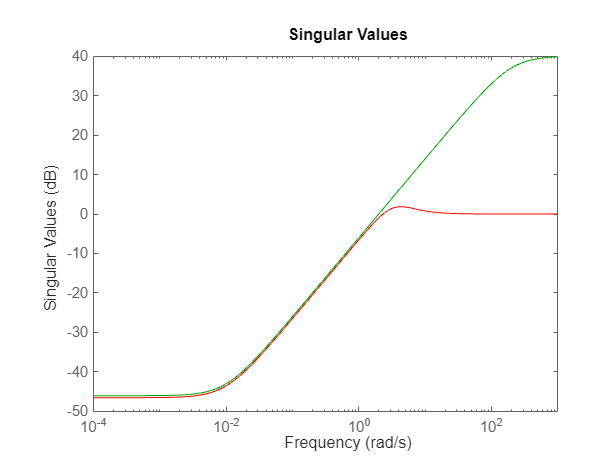

S = feedback(1, L);

figure
sigma(S, 'r');
hold on
sigma(1/W1, 'g');

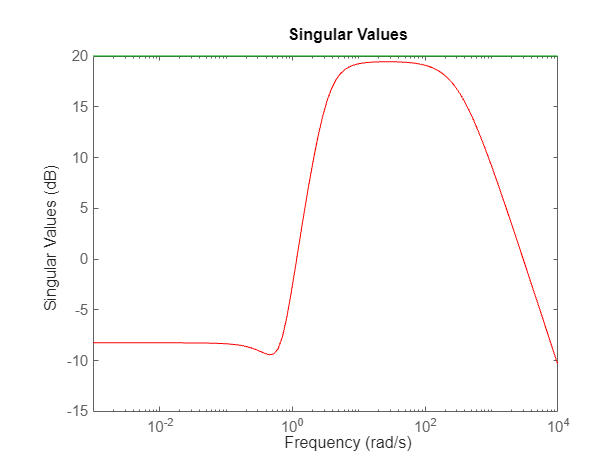

figure
sigma(S*K, 'r')
hold on
sigma(1/W2, 'g')

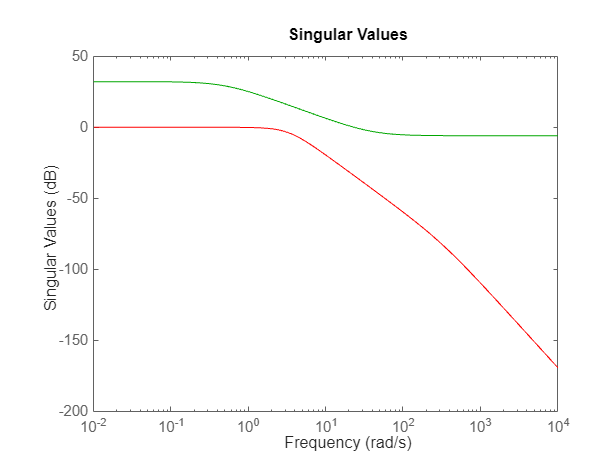

figure
T = feedback(L, 1);
sigma(T, 'r')
hold on
sigma(1/W3, 'g')
hold off


% Mostrar resultados
disp('Valor de gamma (rendimiento):');

Valor de gamma (rendimiento):


gamma

gamma = 0.9446


disp('Controlador H_infinito obtenido:');

Controlador H_infinito obtenido:


K

K =
 
  A = 
               x1          x2          x3          x4
   x1       -0.01   -5.96e-17  -1.691e-14  -3.292e-15
   x2   1.989e-12         -40           8  -1.835e-13
   x3   7.119e-12  -1.188e-14  -3.372e-12           1
   x4        3487      -5.097       -1652      -326.7
 
  B = 
               u1
   x1           1
   x2  -6.187e-15
   x3  -2.214e-14
   x4  -7.038e-15
 
  C = 
          x1     x2     x3     x4
   y1   3037  -4.44  -1438   -284
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


figure
T = K*G

T =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1       -0.01   -5.96e-17  -1.691e-14  -3.292e-15           1           0
   x2   1.989e-12         -40           8  -1.835e-13  -6.187e-15           0
   x3   7.119e-12  -1.188e-14  -3.372e-12           1  -2.214e-14           0
   x4        3487      -5.097       -1652      -326.7  -7.038e-15           0
   x5           0           0           0           0           0           1
   x6           0           0           0           0     -0.4464       -0.68
 
  B = 
          u1
   x1      0
   x2      0
   x3      0
   x4      0
   x5      0
   x6  1.148
 
  C = 
          x1     x2     x3     x4     x5     x6
   y1   3037  -4.44  -1438   -284      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


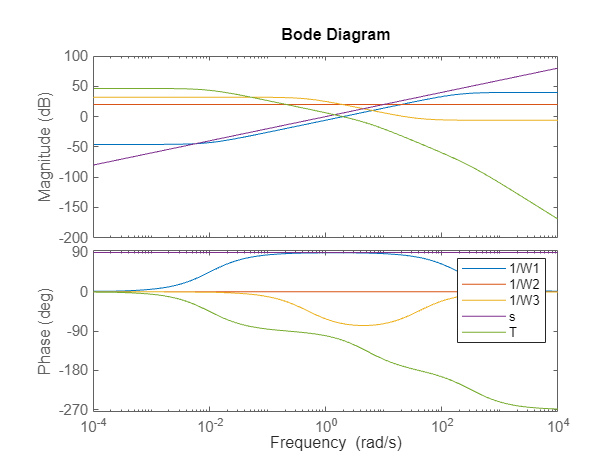

bode(1/W1,1/W2,1/W3,s,T)
legend('1/W1', '1/W2','1/W3', 's','T');

T_s = 0.01

T_s = 0.0100

h_inf = K

h_inf =
 
  A = 
               x1          x2          x3          x4
   x1       -0.01   -5.96e-17  -1.691e-14  -3.292e-15
   x2   1.989e-12         -40           8  -1.835e-13
   x3   7.119e-12  -1.188e-14  -3.372e-12           1
   x4        3487      -5.097       -1652      -326.7
 
  B = 
               u1
   x1           1
   x2  -6.187e-15
   x3  -2.214e-14
   x4  -7.038e-15
 
  C = 
          x1     x2     x3     x4
   y1   3037  -4.44  -1438   -284
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


h_inf_discreto = c2d(K, T_s, 'least-squares')

h_inf_discreto =
 
  A = 
             x1        x2        x3        x4
   x1   -0.2945  0.006205   -0.1249    0.4731
   x2         0    0.9512         1         0
   x3         0         0    0.9999    0.1597
   x4         0         0         0     -1.51
 
  B = 
           u1
   x1   1.218
   x2       0
   x3  0.4109
   x4   1.554
 
  C = 
            x1       x2       x3       x4
   y1    1.743  0.02919  -0.5876    2.226
 
  D = 
          u1
   y1  5.727
 
Sample time: 0.01 seconds
Discrete-time state-space model.


sis_estados= ss(Aa, Bb, C, 0); %Representación en espacio de estados del sistema 
sis_discreto = c2d(sis_estados, T_s);  % Discretización del sistema